# SVM Model 

clc;clear;
% load data 
[train_x, train_y, test_x, test_y, classes] = load_data;
data = [train_x, train_y; test_x, test_y];
% Train binary classification model of SVM 
SVMModel = fitcsvm(data(:,1:26), data(:,27));
% Using cross validation 
SVMMdl = crossval(SVMModel)

SVMMdl =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'  'x22'  'x23'  'x24'  'x25'  'x26'}
           ResponseName: 'Y'
        NumObservations: 169
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


% Class labels; 0 represents non-COVID patient and 1 represents COVID
% patient
classOrder = SVMModel.ClassNames 

classOrder =      0
     1


% predicting the label of the test set 
label = kfoldPredict(SVMMdl)

label =      0
     0
     0
     0
     1
     0
     0
     1
     0
     1


% calculating the accuracy of the model 
accuracy = sum(label == data(:,27))/length(data(:,27))

accuracy = 0.9349

% resubstitution error 
svmResuberror = kfoldLoss(SVMMdl)

svmResuberror = 0.0651

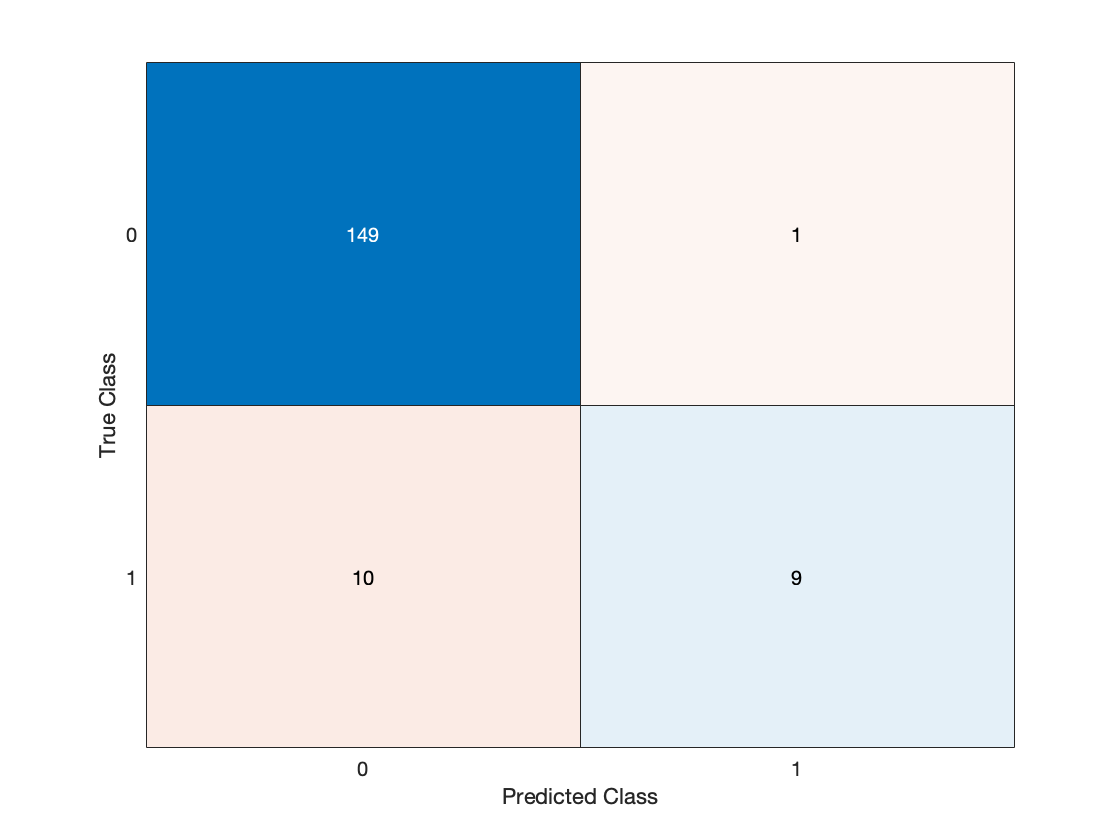

% confusion matrix 
confusionchart(data(:,27),label)

# Decision Tree Model 

clc;clear; 
dt = fitctree(data(:,1:26), data(:,27), 'CrossVal','On')

Reference to a cleared variable data.

dtClass = kfoldPredict(dt)
dtResubErr = kfoldLoss(dt)
accuracy = sum(dtClass == data(:,27))/length(data(:,27))
deResubCM = confusionchart(data(:,27),dtClass)